# Electrohydrodynamics

## Initialization of MATLAB

clear;
close all;
clc

## Analytical Solution

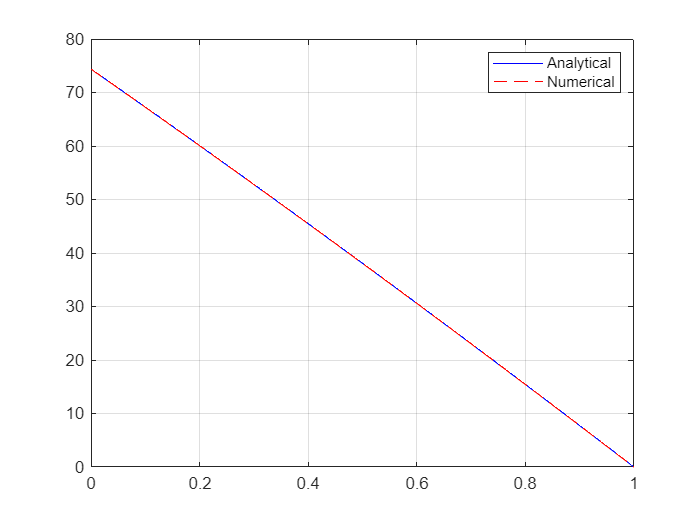

load("numericalValidation.mat")
% Given data (example values — replace with your numbers)
L = 1.0;
phi0 = 74.3924;
q0 = 6.5867e-11;
eps = 8.85419e-12;

% Define F(s0) as above (s0 >= 0)
F = @(s0) (q0/(3*eps))*s0.*(((2*L + s0.^2).^(3/2)) - s0.^3) - phi0;

% Choose bracket or initial guess (s0 positive). Try a few guesses if needed.
s0_initial = max(1e-3, sqrt(abs(2*phi0))); % crude guess
a = 1e-8;
b = 10*max(1, s0_initial);
% If no sign change, you may try fsolve:
opts = optimoptions('fsolve','Display','off','TolFun',1e-12,'TolX',1e-12);
try
    s0 = fsolve(F, s0_initial, opts);
catch
    % fallback to fzero with widened interval (requires sign change)
    s0 = fzero(F, [a b]);
end


c1 = -s0^2;
c2 = - q0/(3*eps) * s0;
c3 = phi0 - c2 * s0^3;

% Optional: verify BCs
y = @(x) c2*(2*x - c1).^(3/2) + c3;
phixx = @(x) 3*c2*(2*x - c1).^(-1/2);
yx3 = @(x) -3*c2*(2*x - c1).^(-3/2);

% fprintf('y(0)=%.6g (target %.6g)\n', y(0), phi0);
% fprintf('y(L)=%.6g (target 0)\n', y(L));
% fprintf('eps*y_xx(0)=%.6g (target %.6g)\n', eps*yxx(0), -q0);
% fprintf('eps*y_xxx(L)=%.6g  (check)\n', eps*yx3(L));
figure;
plot(X,y(X),'b-',"DisplayName","Analytical"); hold on
plot(X,Phi,'r--',"DisplayName","Numerical");
legend;
grid on;

## FOM

%% ---------------- Parameters ----------------
L    = 1.0;           % domain length
Nx   = 1001;           % number of grid points (odd/even doesn't matter)
x    = linspace(0, L, Nx)';
dx   = x(2) - x(1);
muE = 5.3769e-07;

ans = 5.1950e+03

a    = 1/muE;          % PDE parameter
Tend = 35;          % final time
dt   = 1e-1;          % time step (may need to be small for stability)
Nt   = ceil(Tend/dt);

% Boundary condition data
phi0      = 74.3924;        % y(0) = y0
phiL_val  = 0.0;        % y(L) = 0
epsilon = 8.85419e-12;        % epsilon
q0      = 6.5867e-11;        % epsilon*y_xx(0) = -q0  -> y_xx(0) = -q0/epsilon

% Choose whether to (weakly) enforce y_xxx(L)=0
enforce_yxxx_L = true;

% Diagnostic plotting interval
plotEvery = max(1, floor(Nt/100));

%% --------------- Initial condition ---------------
% Start with a smooth initial guess consistent with Dirichlet BCs:
phi = (1 - x/L)*phi0 + (x/L)*phiL_val;    % linear initial profile (satisfies y(0)=y0, y(L)=0)
% Optionally add a small perturbation:
phi = phi + 0.01*sin(pi*x);            

% enforce initial y(1) and y(end) exactly
phi(1) = phi0; phi(end) = phiL_val;

%% --------------- Time stepping ---------------
time = 0;
fprintf('Starting time integration: Nt = %d, dt = %g\n', Nt, dt);

for n = 1:Nt
    % compute derivatives with gradient (Nx x 1)
    phix   = gradient(phi, dx);       % y_x
    phixx  = gradient(phix, dx);      % y_xx
    phixxx = gradient(phixx, dx);     % y_xxx

    % enforce epsilon*y_xx(0) = -q0  -> set yxx(1)
    phixx(1) = -q0 / epsilon;

    % optional: enforce epsilon*y_xxx(L) = 0 (discrete approx)
    % approximate by forcing last two yxx values equal so derivative ~ 0
    if enforce_yxxx_L
        phixx(end) = phixx(end-1);
    end

    % Build RHS at current time level (explicit)
    RHS = phixxx .* phix + phixx.^2;    % Nx x 1

    % Explicit update for yxx (forward Euler)
    % a * (yxx_new - yxx)/dt = RHS   =>   yxx_new = yxx + (dt/a) * RHS
    yxx_new = phixx + (dt / a) .* RHS;

    % Re-enforce boundary yxx(1) and optional yxx(end) after update
    yxx_new(1) = -q0 / epsilon;
    if enforce_yxxx_L
        yxx_new(end) = yxx_new(end-1);
    end

    % ---------- Reconstruct y from yxx_new ----------
    % Integrate once: I1(x) = integral_0^x yxx_new(s) ds (cumtrapz gives vector with I1(1)=0)
    I1 = cumtrapz(x, yxx_new);        % I1(1) = 0

    % Integrate twice: I2(x) = integral_0^x I1(s) ds  (I2(1)=0)
    I2 = cumtrapz(x, I1);

    % The general integrated solution is:
    % yx(x) = I1(x) + C1(t)
    % y(x)  = I2(x) + C1(t)*S(x) + C2(t), where S(x) = cumtrapz(x, ones(size(x)))
    S = cumtrapz(x, ones(size(x)));  % S(1)=0, S(end)=L

    % Enforce Dirichlet BCs:
    % y(0) = C2 = y0  (since I2(1)=0 and S(1)=0)
    C2 = phi0;
    % y(L) = I2(end) + C1*S(end) + C2 = yL_val  => solve for C1
    C1 = (phiL_val - I2(end) - C2) / S(end);   % S(end) should equal L (for uniform x)

    % compute new y (satisfies both Dirichlet BCs exactly)
    phi = I2 + C1 .* S + C2;

    % optional: enforce y(1) and y(end) exactly (numerical safety)
    phi(1) = phi0; phi(end) = phiL_val;

    time = time + dt;
    PhiSnap(:,n) = phi;
    % plotting / progress
    if mod(n,plotEvery) == 0 || n==1 || n==Nt
        clf;
        subplot(2,1,1);
        plot(x, phi, '-k', 'LineWidth', 1.6); hold on;
        plot(x, phix, '--b', 'LineWidth', 1);
        plot(x, yxx_new, ':r', 'LineWidth', 1);
        legend('y','y_x','y_{xx}', 'Location','best');
        title(sprintf('t = %.5f  (step %d/%d)', time, n, Nt));
        xlabel('x'); grid on;

        subplot(2,1,2);
        plot(x, phixxx, '-m', 'LineWidth', 1);
        ylabel('y_{xxx} (approx)'); xlabel('x'); grid on;

        drawnow;
    end
end

fprintf('Finished. Final time = %.6g\n', time);

load("numericalValidation.mat")
figure;
plot(X,Phi,'-','LineWidth', 1.5,"DisplayName","OpenFOAM"); hold on;
plot(x,phi,'--','LineWidth', 1.5,"DisplayName","FDM"); hold on;
plot(X,y(X),'--','LineWidth', 1.5,"DisplayName","Analytical");
xlabel("x",'Interpreter', 'latex');
ylabel("$\phi(x)$",'Interpreter', 'latex');
title("Validation of $\phi(x)$",'Interpreter', 'latex')
legend('Interpreter', 'latex'); 
grid on;
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12, 'LineWidth', 1);
set(gcf, 'Units', 'centimeters', 'Position', [2 2 width height]);
set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperSize', [width height]);
set(gcf, 'PaperPosition', [0 0 width height]);
set(gcf, 'PaperPositionMode', 'manual');
print(gcf, 'Plots/R5f3.pdf', '-dpdf', '-r300');


## ROM

[UPhi,SPhi,~] = svd(PhiSnap,'econ');
cumE = cumsum(diag(SPhi).^2) / sum(diag(SPhi).^2);
rPhi= find(cumE>= 0.999, 1);
UPhi = UPhi(:,1:rPhi);